显式欧拉法步长0.01

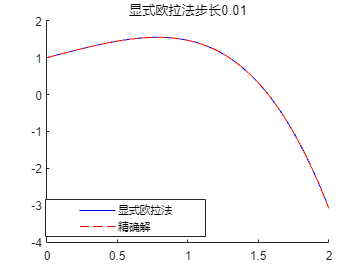

clc
clear
clf ('reset')
Hfun=@(t,u)(-99*u+exp(t)*(100*cos(t)-sin(t)));
k = [0 2];
h = 0.01;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = ODE_ExplicitEuler( Hfun,k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("显式欧拉法","精确解")
hold off
title("显式欧拉法步长0.01");
legend("Position", [0.14052,0.13406,0.4116,0.12684]);

TAB=table(T1,U1,U2,U3);

显式欧拉法步长0.02

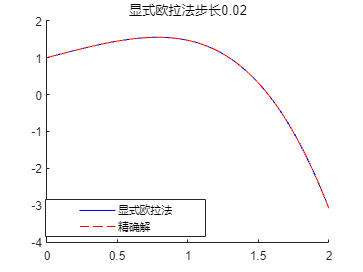

clc
clear
clf ('reset')
Hfun=@(t,u)(-99*u+exp(t)*(100*cos(t)-sin(t)));
k = [0 2];
h = 0.02;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = ODE_ExplicitEuler( Hfun,k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("显式欧拉法","精确解")
hold off
title("显式欧拉法步长0.02")
legend("Position", [0.14052,0.13406,0.4116,0.12684])

TAB=table(T1,U1,U2,U3);

显式欧拉法步长0.03 (不稳定)

clc
clear
clf ('reset')
Hfun=@(t,u)(-99*u+exp(t)*(100*cos(t)-sin(t)));
k = [0 2];
h = 0.03;
u0 = 0;
n=fix(2/h)+1;
[T1,U1] = ODE_ImplicitEuler( Hfun,k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=abs(U1(i)-T1(i).^(-2)*(exp(T1(i))-exp(1)));
U3(i)=T1(i).^(-2)*(exp(T1(i))-exp(1));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1);
plot(T1,U3);
legend("显式欧拉法","精确解")
hold off
title("显式欧拉法步长0.03")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3);
E3=zeros(1,n);
E3=U3;

改进欧拉法步长0.01

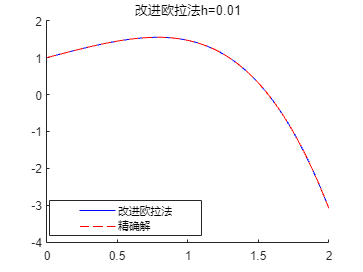

clc
clear
clf ('reset')
Hfun=@(t,u)(-99*u+exp(t)*(100*cos(t)-sin(t)));
k = [0 2];
h = 0.01;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = ODE_ImprovedEuler( Hfun,k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("改进欧拉法","精确解")
hold off
title("改进欧拉法h=0.01")
legend("Position", [0.14052,0.13406,0.4116,0.12684])

TAB=table(T1,U1,U2,U3);
E4=zeros(1,n);
E4=U3;

改进欧拉法步长0.02

clc
clear
clf ('reset')
Hfun=@(t,u)(-99*u+exp(t)*(100*cos(t)-sin(t)));
k = [0 2];
h = 0.02;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = ODE_ImprovedEuler( Hfun,k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("改进欧拉法","精确解")
hold off
title("改进欧拉法h=0.02")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3);
E5=zeros(1,n);
E5=U3;

改进的欧拉步长0.03(不稳定)

clc
clear
clf ('reset')
Hfun=@(t,u)(-99*u+exp(t)*(100*cos(t)-sin(t)));
k = [0 2];
h = 0.03;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = ODE_ImprovedEuler( Hfun,k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("改进欧拉法","精确解")
hold off
title("改进欧拉法h=0.03")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3);
E6=zeros(1,n);
E6=U3;

梯形公式步长0.01

clc
clear
clf ('reset')
k = [0 2];
h = 0.01;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = ODE_TIXING(k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("梯形法","精确解")
hold off
title("梯形法h=0.01")
legend("Position", [0.14052,0.13406,0.4116,0.12684])

legend("Position", [0.15868,0.1299,0.43904,0.13517])
TAB=table(T1,U1,U2,U3)

梯形公式步长0.02

clc
clear
clf ('reset')
k = [0 2];
h = 0.02;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = ODE_TIXING(k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("梯形法","精确解")
hold off
title("梯形法h=0.02")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3)

梯形公式步长0.03

clc
clear
clf ('reset')
k = [0 2];
h = 0.03;
n=fix(2/h)+1;
u0 = 1;
[T1,U1] = ODE_TIXING(k,h,u0 );
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("梯形法","精确解")
hold off
title("梯形法h=0.03")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3)

四阶Runge-Kutta 步长0.01

clc
clear
clf ('reset')
t=[0 2];
u0 = 1;
h = 0.01;
n=fix(2/h)+1;
[T1,U1] = RungeKutta4(t ,u0, h);
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
T1=T1.';
U1=U1.';
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("四阶Runge-Kutta法","精确解")
hold off
title("四阶Runge-Kutta法h=0.01")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3)

四阶Runge-Kutta 步长0.02

clc
clear
clf ('reset')
t=[0 2];
u0 = 1;
h = 0.02;
n=fix(2/h)+1;
[T1,U1] = RungeKutta4(t ,u0, h);
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
T1=T1.';
U1=U1.';
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("四阶Runge-Kutta法","精确解")
hold off
title("四阶Runge-Kutta法h=0.02")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3)

四阶Runge-Kutta 步长0.03(不稳定)

clc
clear
clf ('reset')
t=[0 2];
u0 = 1;
h = 0.03;
n=fix(2/h)+1;
[T1,U1] = RungeKutta4(t ,u0, h);
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
T1=T1.';
U1=U1.';
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("四阶Runge-Kutta法","精确解")
hold off
title("四阶Runge-Kutta法h=0.03")
legend("Position", [0.14052,0.13406,0.2,0.1])

legend("Position", [0.15936,0.13773,0.43478,0.16216])
TAB=table(T1,U1,U2,U3)

Adams 4步4阶显式公式 步长0.001

clc
clear
clf ('reset')
t=[0 2];
u0 = 1;
h = 0.003;
n=fix(2/h)+1;
[T1,U1] = Adams4(t, u0, h);
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
T1=T1.';
U1=U1.';
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("Adams四步四阶法","精确解")
hold off
title("Adams四步四阶法h=0.001")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3)
plot(T1,U3)
title("误差")
legend("步长0.001")

Adams 4步4阶显式公式 步长0.01(不稳定)

clc
clear
clf ('reset')
t=[0 2];
u0 = 1;
h = 0.02;
n=fix(2/h)+1;
[T1,U1] = Adams4(t, u0, h);
U2=zeros(1,n);
U3=zeros(1,n);
for i=1:n
U2(i)=exp(T1(i))*cos(T1(i));
U3(i)=abs(U1(i)-exp(T1(i))*cos(T1(i)));
end
T1=T1.';
U1=U1.';
U2=U2.';
U3=U3.';
hold on
plot(T1,U1,"b-");
plot(T1,U2,"r--");
legend("Adams四步四阶法","精确解")
hold off
title("Adams四步四阶法h=0.01")
legend("Position", [0.14052,0.13406,0.4116,0.12684])
TAB=table(T1,U1,U2,U3)
